clear all
close all
clc

addpath('dace')
Ms = csvread('./data/mysqlResult_transfer1.csv', 1, 0);
Mx = csvread('./data/mysqlResult_transfer2.csv', 1, 0);
% Mx=csvread('./data/new_train.csv',1,0)
Mval = csvread('./data/transfer_tw.csv',1,0);

label=Ms(:,11)

label =    97.1000
   96.9700
   96.7600
   95.3600
   95.0300
   94.5200
   91.1600
   91.0200
   85.4600
   83.7600


label_s=floor(label/10)

label_s =      9
     9
     9
     9
     9
     9
     9
     9
     8
     8


label=Mx(:,11)

label =    97.2200
   77.6300
   75.6100
   73.6500
   69.1000
   66.4100
   63.5300
   63.1900
   62.8700
   62.4800


label_x=floor(label/10)

label_x =      9
     7
     7
     7
     6
     6
     6
     6
     6
     6



no_dims=2

no_dims = 2

initial_dims=10

initial_dims = 10

perplexity=30

perplexity = 30


mappedX=tsne(Ms(:,1:10))

mappedX =    21.0171  -10.1167
   -2.0291   32.7252
  -38.0471  -21.6425
   17.5518   -0.4071
   -9.4450    2.5951
  -13.0546    4.5228
   20.6526   25.9836
   25.8555   21.9988
  -12.3057    2.5209
   17.9455    1.2306


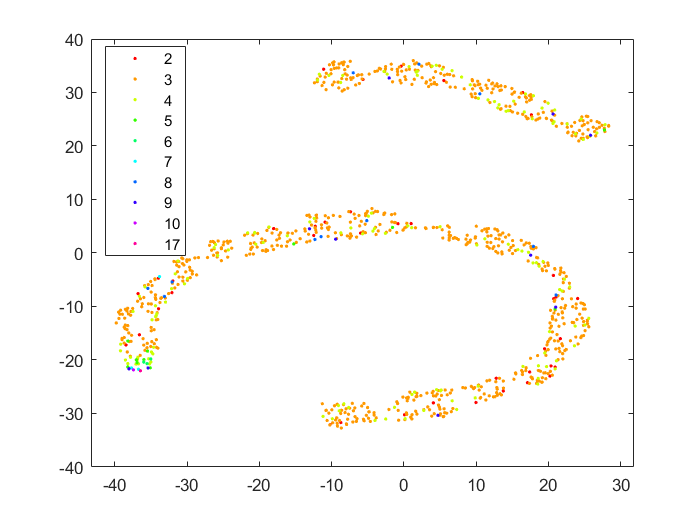

gscatter(mappedX(:,1),mappedX(:,2),label_s)


mappedX=tsne(Mx(:,1:10))

mappedX =    18.3979  -13.4553
   18.6646  -13.1847
   17.9839  -13.1803
   18.4573  -13.0796
   17.9057  -12.3279
   18.6432  -12.7165
   17.6677  -12.2740
   17.8279  -10.5177
   18.2959  -12.7437
   17.5220  -12.7734


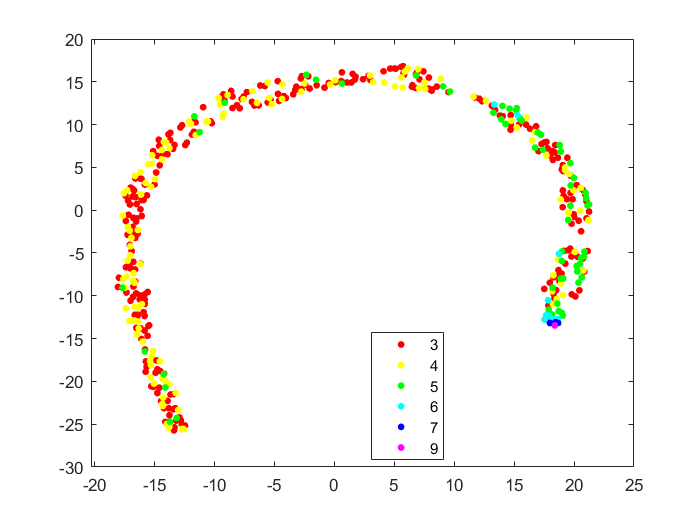

gscatter(mappedX(:,1),mappedX(:,2),label_x)


[pc,score,latent,tsquare]=pca(Ms(:,1:10))

pc =     1.0000   -0.0013    0.0003   -0.0002   -0.0002    0.0001   -0.0000   -0.0000   -0.0000   -0.0000
    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    1.0000    0.0002   -0.0008
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0008    0.0072    1.0000
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0002    1.0000   -0.0072
    0.0001   -0.0003   -0.0043    0.0002    0.7704    0.6375    0.0001    0.0000   -0.0000   -0.0000
   -0.0001   -0.0011   -0.0057   -0.0051   -0.6376    0.7704    0.0001    0.0000   -0.0000   -0.0000
   -0.0000    0.0211    0.7919    0.6102   -0.0024    0.0080    0.0000    0.0000   -0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0001    1.0000    0.0000    0.0000    0.0000
    0.0013    0.9997   -0.0120   -0.0191   -0.0004    0.0008    0.0000    0.0000    0.0000    0.0000
    0.0004    0.0078   -0.6105    0.7920   -0.0025   -0.0013    0.0000   -0.0000   -0.

score = 	1.0e+09 *

   -0.0875   -0.0615   -0.0243    0.0042   -0.0012   -0.0041   -0.0000   -0.0000    0.0000   -0.0000
    0.9606    0.0107   -0.0016   -0.0104   -0.0087   -0.0014   -0.0000   -0.0000    0.0000    0.0000
   -1.5510    0.0531    0.0268   -0.0198    0.0017    0.0064    0.0000    0.0000    0.0000    0.0000
   -0.3166   -0.0038    0.0131    0.0159    0.0083    0.0024   -0.0000   -0.0000   -0.0000   -0.0000
   -0.8073    0.0438   -0.0363    0.0028    0.0045   -0.0004   -0.0000   -0.0000    0.0000    0.0000
   -0.8482   -0.0089    0.0161    0.0298    0.0007   -0.0020   -0.0000   -0.0000   -0.0000   -0.0000
    1.4767    0.0147    0.0285    0.0065   -0.0030   -0.0090   -0.0000   -0.0000   -0.0000    0.0000
    1.6035    0.0171    0.0054   -0.0232   -0.0029   -0.0067    0.0000   -0.0000   -0.0000    0.0000
   -0.8476    0.0462   -0.0147    0.0142    0.0033    0.0065   -0.0000   -0.0000   -0.0000   -0.0000
   -0.3147    0.0574   -0.0154   -0.0269    0.0044    0.0048    0.0000 

latent = 	1.0e+17 *

    8.8777
    0.0157
    0.0039
    0.0034
    0.0002
    0.0002
    0.0000
    0.0000
    0.0000
    0.0000


tsquare =     4.7727
    5.9912
   12.1930
    4.4742
    6.7323
    5.6090
    8.6825
    7.0928
    5.7642
    7.4900


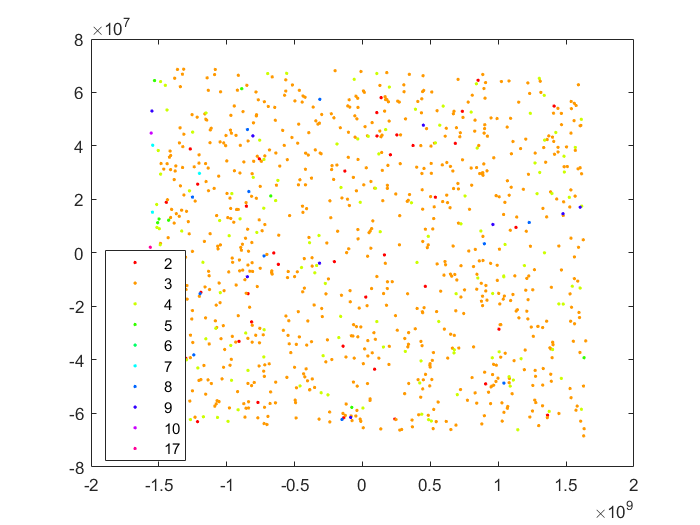

gscatter(score(:,1),score(:,2),label_s)

[pc,score,latent,tsquare]=pca(Mx(:,1:10))

pc =     1.0000   -0.0008    0.0008    0.0009   -0.0003   -0.0002   -0.0000   -0.0000    0.0000   -0.0000
    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    1.0000    0.0003   -0.0002
    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0002    0.0318    0.9995
   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0003    0.9995   -0.0318
    0.0003    0.0040    0.0103   -0.0046    0.3268    0.9450   -0.0001    0.0000   -0.0000    0.0000
    0.0002    0.0033    0.0042    0.0025    0.9451   -0.3268   -0.0001   -0.0000    0.0000   -0.0000
   -0.0011    0.0158    0.9023    0.4307   -0.0071   -0.0054    0.0000    0.0000   -0.0000   -0.0000
    0.0000   -0.0000   -0.0000   -0.0000    0.0001    0.0000    1.0000   -0.0000    0.0000   -0.0000
    0.0008    0.9993    0.0004   -0.0375   -0.0044   -0.0029    0.0000    0.0000   -0.0000   -0.0000
   -0.0004    0.0340   -0.4310    0.9017    0.0022    0.0082    0.0000    0.0000    0.

score = 	1.0e+09 *

   -1.4884   -0.0465   -0.0135    0.0292   -0.0033    0.0062    0.0000   -0.0000    0.0000   -0.0000
   -1.4760   -0.0255    0.0289   -0.0197    0.0018    0.0042    0.0000   -0.0000   -0.0000   -0.0000
   -1.4733   -0.0166   -0.0358    0.0023    0.0028   -0.0021    0.0000    0.0000    0.0000   -0.0000
   -1.4722   -0.0219    0.0050   -0.0026    0.0065   -0.0059   -0.0000    0.0000    0.0000    0.0000
   -1.4452    0.0148    0.0101    0.0138   -0.0038    0.0004    0.0000    0.0000   -0.0000    0.0000
   -1.4521   -0.0222   -0.0113   -0.0188   -0.0081   -0.0049    0.0000   -0.0000   -0.0000   -0.0000
   -1.4395    0.0177   -0.0147   -0.0427   -0.0046    0.0021   -0.0000   -0.0000   -0.0000    0.0000
   -1.3611    0.0333    0.0179    0.0246   -0.0102   -0.0039    0.0000    0.0000   -0.0000    0.0000
   -1.4615   -0.0115    0.0002    0.0051    0.0029    0.0034   -0.0000    0.0000   -0.0000    0.0000
   -1.4660    0.0365   -0.0029    0.0283    0.0044   -0.0036   -0.0000 

latent = 	1.0e+17 *

    8.3053
    0.0146
    0.0036
    0.0033
    0.0002
    0.0002
    0.0000
    0.0000
    0.0000
    0.0000


tsquare =     9.6156
    9.4582
    8.6815
    6.4306
    4.7920
   10.0144
   10.9967
   10.7689
    4.4475
    9.8971


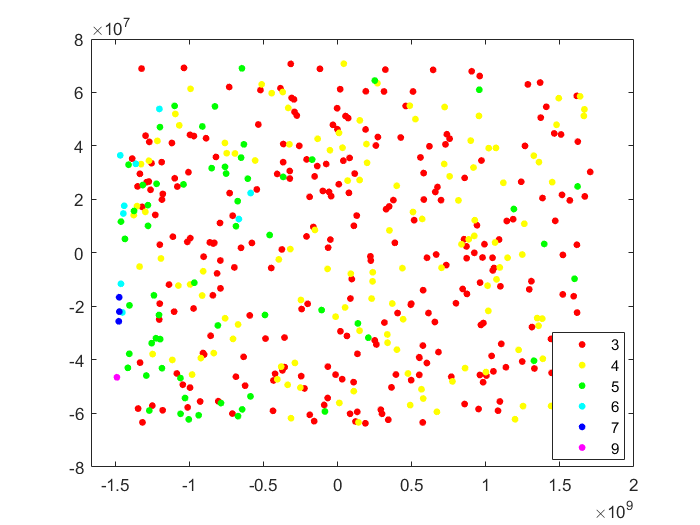

gscatter(score(:,1),score(:,2),label_x)

label=Mval(:,11)

label =    69.8700
   64.0000
   59.7100
   56.6500
   54.4300
   52.9700
   49.8700
   48.5900
   48.5500
   47.7300


label_s=floor(label/10)

label_s =      6
     6
     5
     5
     5
     5
     4
     4
     4
     4


label=Mval(:,12)

label =    73.6500
   62.8700
   56.7700
   97.2200
   47.8800
   69.1000
   42.3000
   77.6300
   57.7600
   66.4100


label_x=floor(label/10)

label_x =      7
     6
     5
     9
     4
     6
     4
     7
     5
     6



no_dims=2

no_dims = 2

initial_dims=10

initial_dims = 10

perplexity=30

perplexity = 30


mappedX=tsne(Mval(:,1:10))

mappedX =     7.4297   23.3327
    7.6305   23.2587
    7.5358   22.4981
    7.3145   23.1769
    8.5329   22.4100
    8.1714   23.3080
  -17.7565   -5.8625
    7.6032   23.4799
    8.0778   23.4570
    7.3842   22.8685


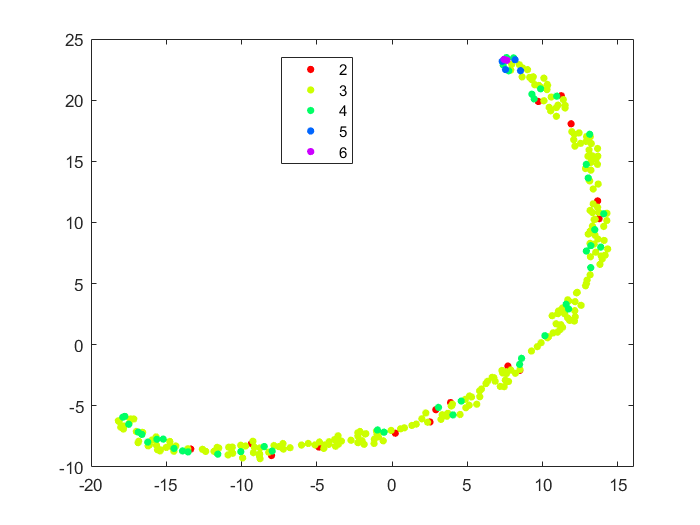

gscatter(mappedX(:,1),mappedX(:,2),label_s)

mappedX=tsne(Mval(:,1:10))

mappedX =    16.1694    1.4265
   15.8730    1.1921
   16.0129    0.5852
   16.3191    1.4802
   15.1141    0.2704
   15.4010    1.3282
   -2.3443   29.2600
   15.7886    1.7065
   15.5419    1.5223
   16.0237    1.0056


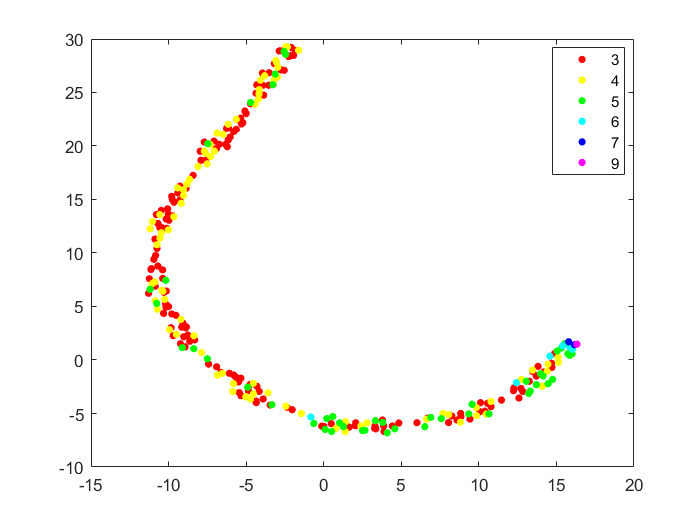

gscatter(mappedX(:,1),mappedX(:,2),label_x)


[pc,score,latent,tsquare]=pca(Mval(:,1:10))

pc =     1.0000    0.0010    0.0007    0.0014   -0.0002   -0.0003    0.0000   -0.0000    0.0000   -0.0000
    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    1.0000    0.0006   -0.0004
    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0004    0.0112    0.9999
   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0006    0.9999   -0.0112
    0.0003    0.0047    0.0123   -0.0042    0.0374    0.9992   -0.0002    0.0000    0.0000    0.0000
    0.0001    0.0046    0.0081   -0.0009    0.9993   -0.0375   -0.0001   -0.0000    0.0000   -0.0000
   -0.0014    0.0069    0.7937    0.6082   -0.0062   -0.0070    0.0000    0.0000   -0.0000   -0.0000
   -0.0000   -0.0000   -0.0000    0.0000    0.0001    0.0001    1.0000    0.0000    0.0000   -0.0000
   -0.0010    0.9999   -0.0115    0.0036   -0.0047   -0.0044    0.0000    0.0000   -0.0000   -0.0000
   -0.0006   -0.0098   -0.6080    0.7938    0.0061    0.0106   -0.0000   -0.0000    0.

score = 	1.0e+09 *

   -1.4496   -0.0258    0.0060   -0.0030    0.0080   -0.0041   -0.0000    0.0000    0.0000    0.0000
   -1.4388   -0.0158   -0.0005    0.0040    0.0019    0.0037   -0.0000    0.0000    0.0000    0.0000
   -1.3921   -0.0480    0.0061    0.0290    0.0049   -0.0063   -0.0000   -0.0000   -0.0000    0.0000
   -1.4657   -0.0519   -0.0182    0.0233   -0.0047    0.0047    0.0000   -0.0000    0.0000   -0.0000
   -1.3521    0.0100    0.0132    0.0132   -0.0005   -0.0018   -0.0000   -0.0000   -0.0000   -0.0000
   -1.4226    0.0102    0.0069    0.0157   -0.0037   -0.0010    0.0000    0.0000   -0.0000    0.0000
    1.6876    0.0548    0.0088    0.0147    0.0053    0.0021   -0.0000   -0.0000   -0.0000    0.0000
   -1.4533   -0.0284    0.0330   -0.0148    0.0003    0.0042    0.0000   -0.0000   -0.0000   -0.0000
   -1.4387    0.0074   -0.0091    0.0032    0.0046   -0.0030   -0.0000    0.0000    0.0000    0.0000
   -1.4294   -0.0255   -0.0067   -0.0221   -0.0063   -0.0074    0.0000 

latent = 	1.0e+17 *

    8.6172
    0.0146
    0.0039
    0.0029
    0.0003
    0.0002
    0.0000
    0.0000
    0.0000
    0.0000


tsquare =     6.4214
    4.6225
   13.2224
    8.9834
    4.1573
    4.4541
    8.5229
    9.1061
    6.3709
   10.6902


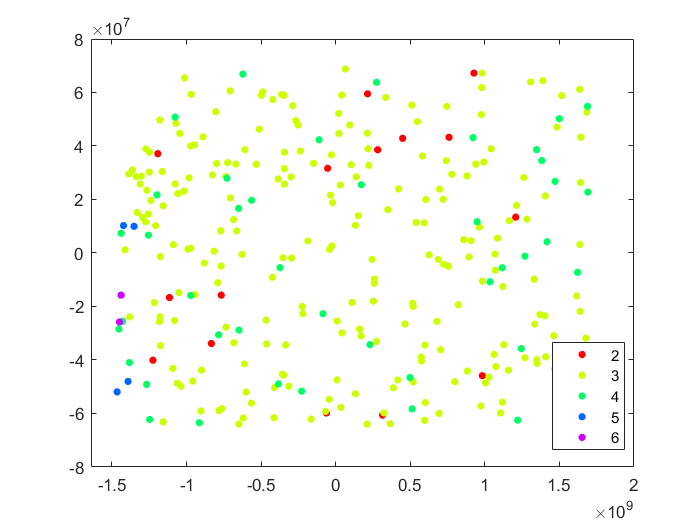

gscatter(score(:,1),score(:,2),label_s)

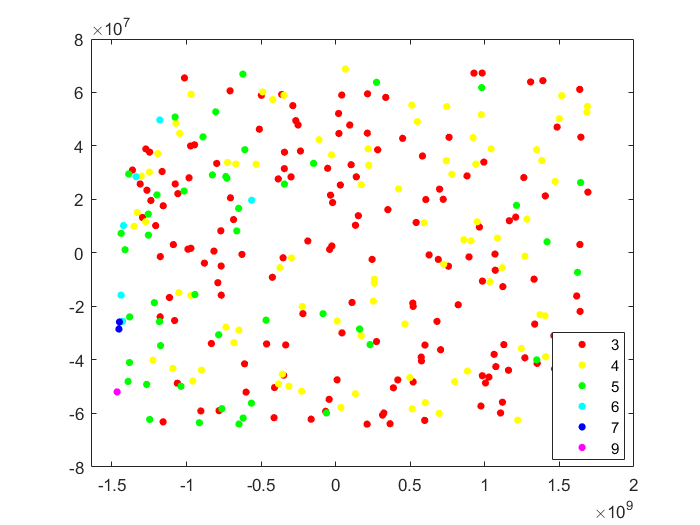

gscatter(score(:,1),score(:,2),label_x)

[pc,score,latent,tsquare]=pca(Mval(:,1:10))

pc =     1.0000    0.0010    0.0007    0.0014   -0.0002   -0.0003    0.0000   -0.0000    0.0000   -0.0000
    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    1.0000    0.0006   -0.0004
    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0004    0.0112    0.9999
   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0006    0.9999   -0.0112
    0.0003    0.0047    0.0123   -0.0042    0.0374    0.9992   -0.0002    0.0000    0.0000    0.0000
    0.0001    0.0046    0.0081   -0.0009    0.9993   -0.0375   -0.0001   -0.0000    0.0000   -0.0000
   -0.0014    0.0069    0.7937    0.6082   -0.0062   -0.0070    0.0000    0.0000   -0.0000   -0.0000
   -0.0000   -0.0000   -0.0000    0.0000    0.0001    0.0001    1.0000    0.0000    0.0000   -0.0000
   -0.0010    0.9999   -0.0115    0.0036   -0.0047   -0.0044    0.0000    0.0000   -0.0000   -0.0000
   -0.0006   -0.0098   -0.6080    0.7938    0.0061    0.0106   -0.0000   -0.0000    0.

score = 	1.0e+09 *

   -1.4496   -0.0258    0.0060   -0.0030    0.0080   -0.0041   -0.0000    0.0000    0.0000    0.0000
   -1.4388   -0.0158   -0.0005    0.0040    0.0019    0.0037   -0.0000    0.0000    0.0000    0.0000
   -1.3921   -0.0480    0.0061    0.0290    0.0049   -0.0063   -0.0000   -0.0000   -0.0000    0.0000
   -1.4657   -0.0519   -0.0182    0.0233   -0.0047    0.0047    0.0000   -0.0000    0.0000   -0.0000
   -1.3521    0.0100    0.0132    0.0132   -0.0005   -0.0018   -0.0000   -0.0000   -0.0000   -0.0000
   -1.4226    0.0102    0.0069    0.0157   -0.0037   -0.0010    0.0000    0.0000   -0.0000    0.0000
    1.6876    0.0548    0.0088    0.0147    0.0053    0.0021   -0.0000   -0.0000   -0.0000    0.0000
   -1.4533   -0.0284    0.0330   -0.0148    0.0003    0.0042    0.0000   -0.0000   -0.0000   -0.0000
   -1.4387    0.0074   -0.0091    0.0032    0.0046   -0.0030   -0.0000    0.0000    0.0000    0.0000
   -1.4294   -0.0255   -0.0067   -0.0221   -0.0063   -0.0074    0.0000 

latent = 	1.0e+17 *

    8.6172
    0.0146
    0.0039
    0.0029
    0.0003
    0.0002
    0.0000
    0.0000
    0.0000
    0.0000


tsquare =     6.4214
    4.6225
   13.2224
    8.9834
    4.1573
    4.4541
    8.5229
    9.1061
    6.3709
   10.6902


pc(:,1)

ans =     1.0000
    0.0000
    0.0000
   -0.0000
    0.0003
    0.0001
   -0.0014
   -0.0000
   -0.0010
   -0.0006


cumsum(latent)./sum(latent)

ans =     0.9975
    0.9992
    0.9996
    0.9999
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


gscatter(score(:,1),score(:,2),label_s)